# Analisi Algoritmo di Bisezione 

In questa documentazione si mostreranno i casi di test relativi all'algoritmo di bisezione.

# Test di accuratezza

Il  test di accuratezza determina quanto la soluzione approssimata trovata attraverso il metodo di bisezione si avvicina alla soluzione dell'algoritmo fzero(). Quest'ultimo è il migliore algoritmo utilizzato per ffff lo zero in Matlab. Ai fini del calcolo dell' accuratezza è stata implementata la funzione CalcoloAccuratezza() . Essa calcola l'errore relativo tra le soluzioni restituite dai due algoritmi al medesimo problema. Una breve documentazione e l'implementazione della funzione è disponibile: 

  doc CalcoloAccuratezza

## **Esempio**

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.

`Command line Matlab`

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];

CalcoloAccuratezza(f,x0,1e-10)
CalcoloAccuratezza(f,x0,1e-11)
CalcoloAccuratezza(f,x0,1e-12)
CalcoloAccuratezza(f,x0,1e-13)
CalcoloAccuratezza(f,x0,1e-14)
CalcoloAccuratezza(f,x0,1e-15)
CalcoloAccuratezza(f,x0,eps)

`Esecuzione da interfaccia grafica`

 MainGUI();

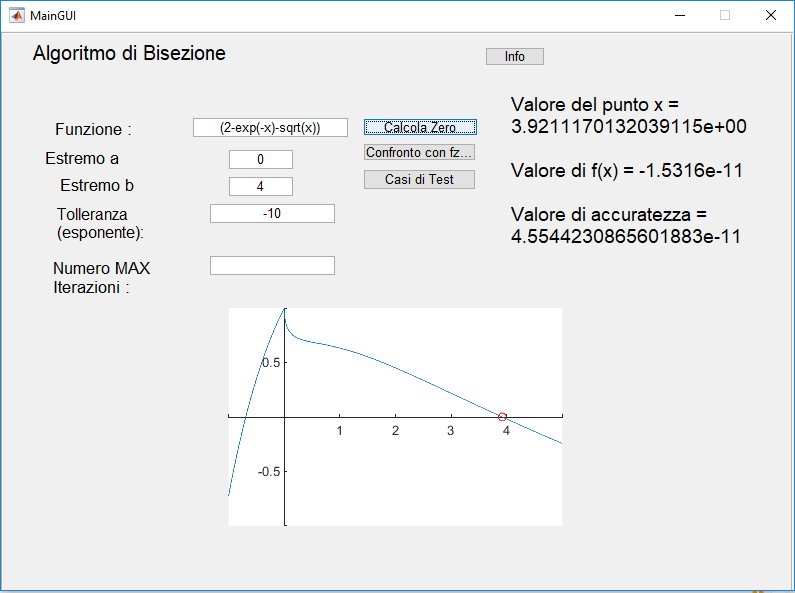

# Valutazione Performance

Si è implementata una funzione che crea un grafico di confronto tra i due algoritmi sopra citati. Si è calcolata la performance confrontando il numero di iterazioni necessarie all'algoritmo di Bisezione con quelle necessarie alla funzione fzero() considerata la tolleranza richiesta. 

## **Esempio**

Calcola la performance dell'algoritmo di bisezione quando è in input f=  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.L La funzione restituirà un grafico di confronto tra i due approcci.

`Command line Matlab`

f = @(x) (2-exp(-x)-sqrt(x));%funzione handle
xo = [0 4];
TOL=[10.^-1 10.^-2 10.^-3  10.^-4 10.^-5 10.^-6 10.^-7 10.^-8 10.^-9 10.^-10 10.^-12 10.^-13 10.^-14 eps];
Valuta_Performance(f,x0,TOL);

`Esecuzione da interfaccia grafica`

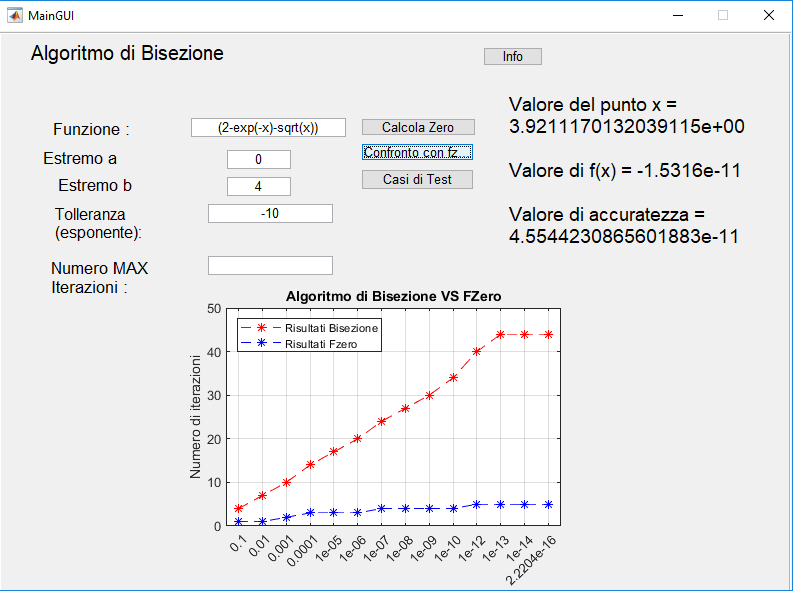

Come si nota dal grafico il numero di iterazioni richieste dalla funzione fzero() è minore rispetto a quelle della funzione algoritmo_di_bisezione() per ogni valore di TOL. Si può osservare che la differenza tra i due approcci è tanto più marcata quanto più si cerca una risoluzione migliore diminuendo la tolleranza.

# Test di robustezza

Per la progettazione dei casi di test è stato utilizzato il metodo di *Category-partition testing *[1], ampiamente diffuso nell'ambito dell'Ingegneria del Software per il testing funzionale. In particolare, le categorie sono state scelte in base ai parametri (di ingresso e uscita) modificabili dall'utente e in base all'ipotesi del teorema degli zeri (su cui si basa l'algoritmo); i valori sono stati scelti in base alle condizioni di errore/warning in cui ci si può venire a trovare.

Il numero di casi di test è: 15 , implementati in una classe sottoforma di funzioni.

Per l'implementazione dei casi di test è stato utilizzato il framework di MatLab per il testing di unità [2]*; *questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione

result1 = runtests('exec_tests.m');
table(result1)

Il sistema esegue in automatico i test, riportando in tabella, i test eseguiti con successo e quelli senza successo un sommario di quanti hanno avuto successo e dettagliando gli errori in quelli che eventualmente sono falliti. 

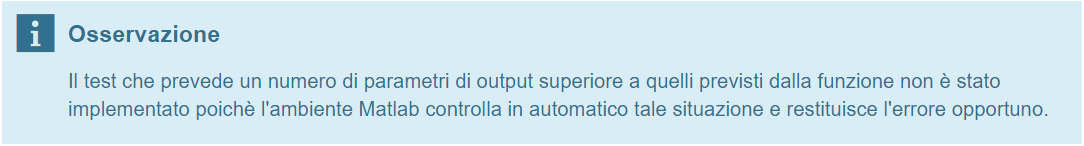

Nella maggioranza dei test sono stati usati dati comuni per cui è stata sfruttata la funzione **Richiama_Parametri** per istanziare i dati comuni ai test case:

function [f,x0,TOL,NMAX] = Richiama_Parametri()
f =  @(x) 2-exp(-x)-sqrt(x);
x0 =[0 4];
TOL = 10^-15;
NMAX = 999;
end

Di seguito viene descritta l'implementazione di alcuni casi di test a titolo esemplificativo.

## Caso di test 1                                                                                                                         

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: vuoto

- `NMAX`: vuoto

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

Viene calcolato lo zero di `fun `sia con `bisection_algorithm `che con `fzero; `confrontando l'errore assoluto con l'epsilon associato al max dei risultati si può decidere se la risoluzione del calcolo è sufficiente.

## Caso di test 12                                                                                                                       

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: valido

- `NMAX`: not numeric

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

In questo caso la funzione di servizio` verifyError() `controlla che l'esecuzione del test generi un errore identificato dall'id` 'bisection_algorithm:ErrorNMAX'.`

## Caso di test 14                                                                                                                       

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: valido

- `NMAX`: 0 < NMAX < 10

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

function testFunctionCase14(testCase)    
    [fun,range] = getGlobalParameter;
    TOL = eps;
    NMAX = 5;
    testCase.verifyWarning(@()bisection_algorithm(fun,range,TOL,NMAX),'bisection_algorithm:WarningMinNMAX')
end

In questo caso il sistema controlla che l'esecuzione del test generi l'appropriato warning all'utente. Non è necessario calcolare l'errore relativo della funzione poichè avendo specificato un numero ridotto di iterazione, non è possibile predire quanto sarà preciso il risultato finale.

## Caso di test 20                                                                                                                         

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: valido

- `NMAX`: 0 < NMAX < 10

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

NOTA: lo zero si trova nell'estremo dell'intervallo

In questo caso non sono stati usati i parametri "globali" usati per i test precedenti. L'obiettivo del test è verificare che l'algoritmo trova subito lo zero se questo è in corrispondenza di uno degli estremi dell'intevallo passato in ingresso; tale controllo viene effettuato considerato il secondo parametro di uscita (`fx`) della funzione.

## Riferimenti                                                                                                                  

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**